# Workspace & Robot Plotting - Example (made-up dimensions)

clc; clear; close all;

## Old Version

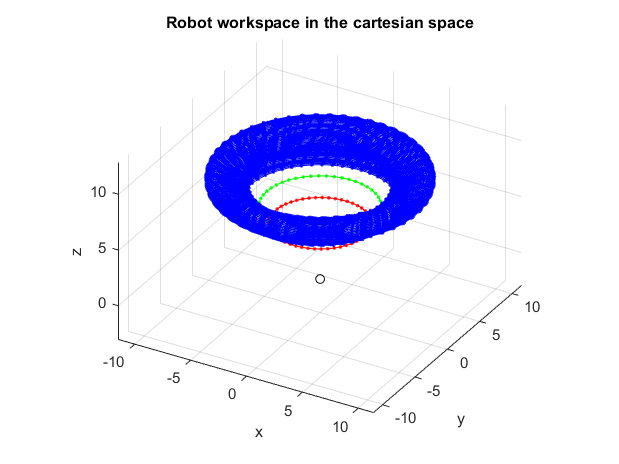

L = [5 4 3 2 1];
angle = pi/6;
limits = [0 2*pi 0 3 -pi*0.5 pi*0.5];

figure
plot_workspace_OLD(L,angle,limits,gcf)

## Current Version

### Workspace

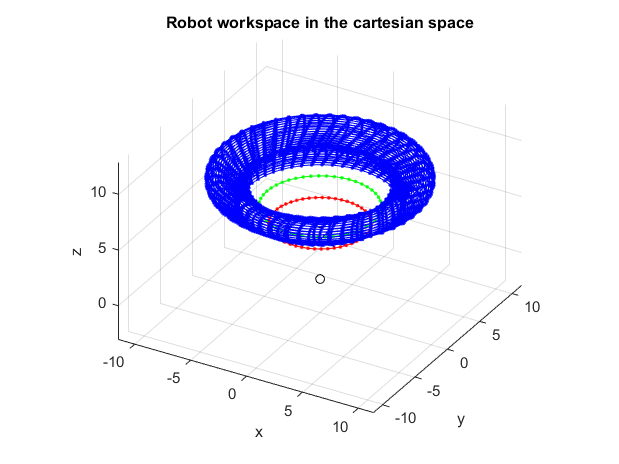

L = [5 4 3 2 1];
angle = pi/6;
limits = [0 2*pi 0 3 -pi*0.5 pi*0.5];
nPoints = [50 15 15];
volume_Flag = 'off';

figure
plot_workspace(L,angle,limits,gcf,nPoints,volume_Flag)

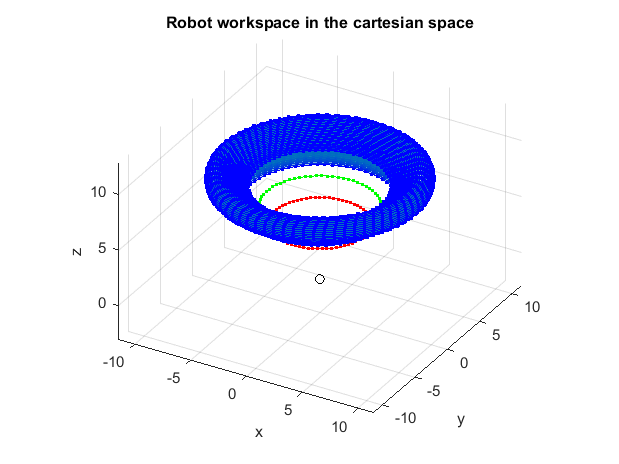

L = [5 4 3 2 1];
angle = pi/6;
limits = [0 2*pi 0 3 -pi*0.5 pi*0.5];
nPoints = [70 20 20];
volume_Flag = 'on';

figure
plot_workspace(L,angle,limits,gcf,nPoints,volume_Flag)

### Manipulator

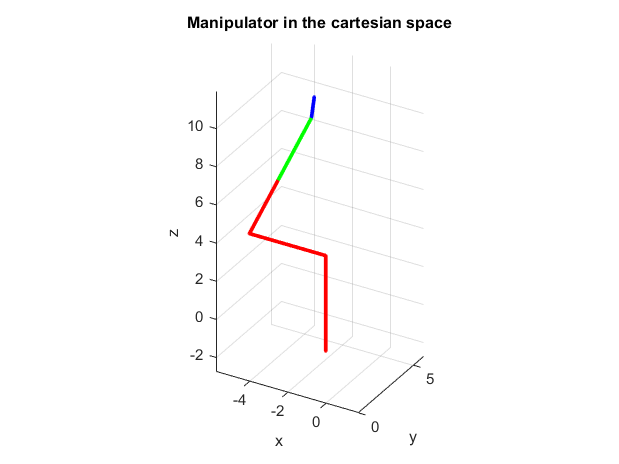

Q = {pi; 1.5; 0.25*pi};

figure
plot_robot(Q,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Manipulator in the cartesian space')

## Check Inverse Kinematics

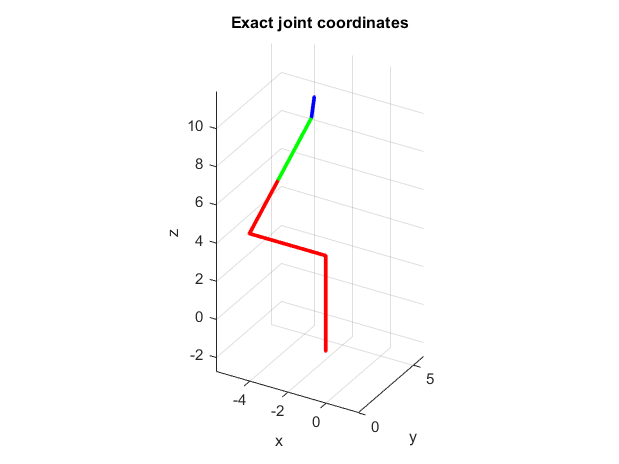

Q = {pi; 1.5; 0.25*pi};
[S,~] = dir_kin(Q,L,angle);

sol = 1;
Q_inv_kin = inv_kin(S,L,angle,sol);

figure
plot_robot(Q,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Exact joint coordinates')


figure
plot_robot(Q_inv_kin,L,angle,gcf)

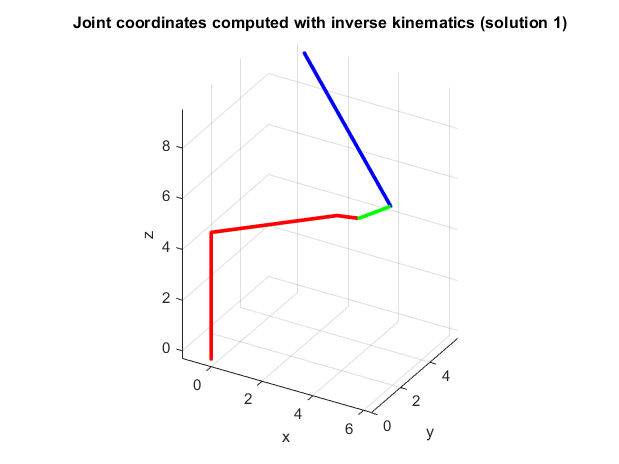

grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Joint coordinates computed with inverse kinematics (solution 1)')